# MATH2089 Week 1 Lab

## Question 1

*It is recommended that you use the lab computers in Linux, since your mid-term exam will also be in Linux. Note that, when using MATLAB in Linux, *`copy::Alt+W`* and *`paste::Ctrl+Y`*.*

The first question of this term simply guides you through importing data into MATLAB. We want to perform statistical analyses on data sets. It is generally easier to just import the data into MATLAB, rather than retyping and storing the data.

The first thing we need to do is download the data set into an accessible directory. It is recommended that you create a MATH2089 folder `in your` H `drive.` The H drive is cloud drive that can be accessed from any computer on campus, through myAccess Apps, or myfiles. Now that we have set up the folder, let's download all the data sets. Go to

UNSW Moodle > MATH2089 > Statistics - useful resources > Datasets for lab classes > Download folder

and save the compressed `.zip` file to your `MATH2089` folder in the `H` drive. Unzip the file and relabel the folder to something appropriate, e.g., *datasets*. Don't include empty space in your folder name, e.g., don't label the folder *data sets.* Alternatively, replace the spaces with underscores ( _ ), e.g., *data_sets*. We don't want spaces (or other illegal folder names) since MATLAB won't be able to read the directory.

We'll use two different ways to import the data

- Using the Import Wizard

- Using the `readvars()` function in MATLAB

### The Import Wizard

To open the Import Wizard, click **Import Data** under the Home tab in MATLAB. This should open a directory. Navigate to where your data sets are stored and select `inflows.txt`. MATLAB will automically identify if the data are labelled and will select the appropriate range. The only thing we need to do is change `Output Type` to `Numeric Matrix`. Then click `Import Selection` and MATLAB will store the data set as the matrix `inflows`.

You can also change `Output Type` to `Column vectors`, which will import each column of the data set as a separate object, e.g., `Year` and `Inflow` from `inflows`.

### readvars()

If we know that the variables of the data set are set out columnwise, then it might be easier to use `readvars()` instead of the point-and-click method required by the Import Wizard. `readvars()` will read in the data set columnwise, so we need to preassign the variables correctly. 

% Change the directory using cd to where the file location.
cd /srv/hdrive/z3417078/teaching/MATH2089/data

% Read in the data as column vectors using readvars().
% The first column of the data set is the year, which we don't need. We can
% suppress storing that variable by writing '~' in its position.
% Writing a semi-colon (;) at the end prevents printing to the console.
[~, inflow] = readvars("inflows.txt");

## Question 2

We wish to do some basic descriptive statistics on the `inflows` data set. We already imported the data in Question 1. Let's produce a frquency histogram with appropriate labels.

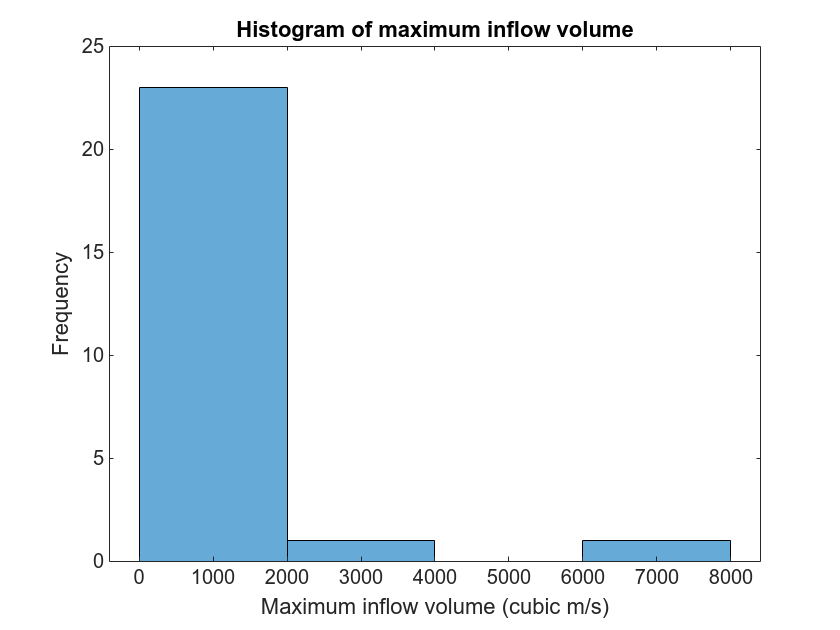

histogram(inflow)
xlabel('Maximum inflow volume (cubic m/s)')
ylabel('Frequency')
title('Histogram of maximum inflow volume')

Executing `help function_name` in the Command Window will produce the documentation for `function_name`, e.g., `help histogram`. 

Now let's take a look at some basic descriptive statistics, such as the sample average, sample standard deviation. 

mean(inflow)

ans = 862.8400

var(inflow)

ans = 1.7170e+06

std(inflow)

ans = 1.3104e+03

The average maximum inflow volume is 862.84 $m^{3}/s$. The standard deviation—which is a measure of the average distance from the sample average—is 1 310.36 $m^{3}/s$. The sample quantile $q\in[0,1]$ identifies the value which is inclusively larger than $100q\%$ of the data. The five-number summary extracts the quantiles for $q$ = 0, 0.25, 0.5, 0.75, and 1. The 0-th and 1-th quantiles respectively identifies the sample minimum and maximum. The 0.5-th quantile identifies the sample median—the middle value. We can use the `quantile()` function in MATLAB. 

% Write the quantiles of interest as a vector
quantiles = 0:0.25:1;

% Use quantile(data, q) to extract the sample quantiles 
quantile(inflow, quantiles)

ans = 1.0e+03 *

    0.0300    0.1842    0.4120    0.8143    6.1000


The sample minimum and maximum are respectively 30 $m^{3}/s$ and 6 100 $m^{3} / s$. The median maximum inflow volume is 412 $m^{3}/s$. The Inter-Quartile Range is the difference between the 0.75-th and 0.25-th sample quantiles, and represents the distance covered by the *central 50% of the data*. We see that the central 50% of the data are separated by 630 $m^{3}/s$, from 184.2–814.3 $m^{3}/s$.

quantile(inflow, 0.75) - quantile(inflow, 0.25)

ans = 630

diff(quantile(inflow, [0.25, 0.75]))

ans = 630

We already looked at *frequency histogram*, which identifies the count for each bin. Histograms can be thought of as quantised representations of the underlying density of the sample. We can change the scale on the vertical axis so that the histogram *integrates to 1*, i.e., the sum of areas of the bins adds to 1. 

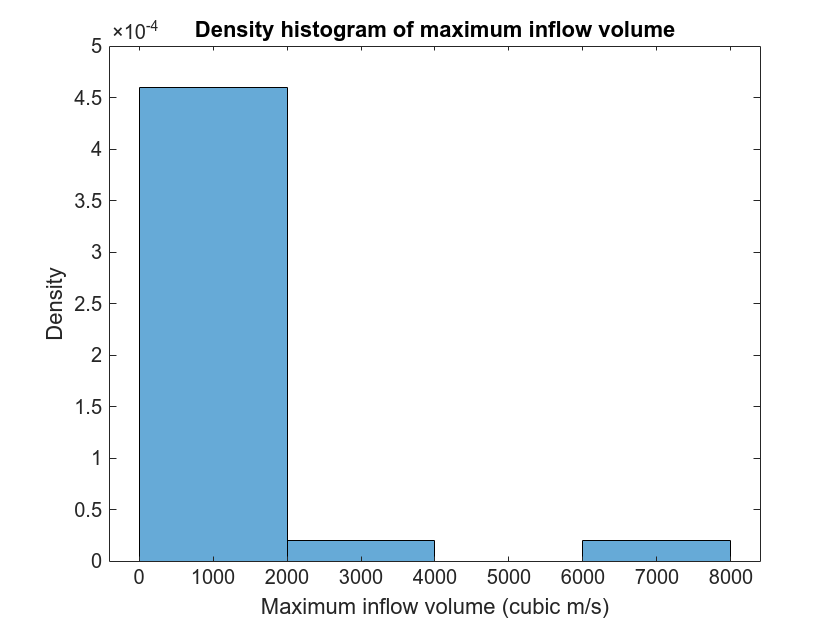

histogram(inflow, 'Normalization', 'pdf')
xlabel('Maximum inflow volume (cubic m/s)')
ylabel('Density')
title('Density histogram of maximum inflow volume')

We see that the vertical axis has changed scale to the order of $10^{-4}$. The heights of each of the four generated bins are, from left-to-right, $4.6\times10^{-4}$, $2\times 10^{-5}$, 0, and $2\times 10^{-5}$. Each bin has width 2 000. It follows that the histogram is a valid density since

$2000\cdot4.6\times10^{-4} + 2000\cdot2\times10^{-5} + 2000\cdot0\times10 + 2000\cdot2\times10^{-5} = 1$.

The histogram doesn't seem to be informative since most of the data is concentrated in the first bin. Let's increase the number of bins. Use `help histogram` to identify how to increase the number of bins. Let's use $n = 5$ bins.

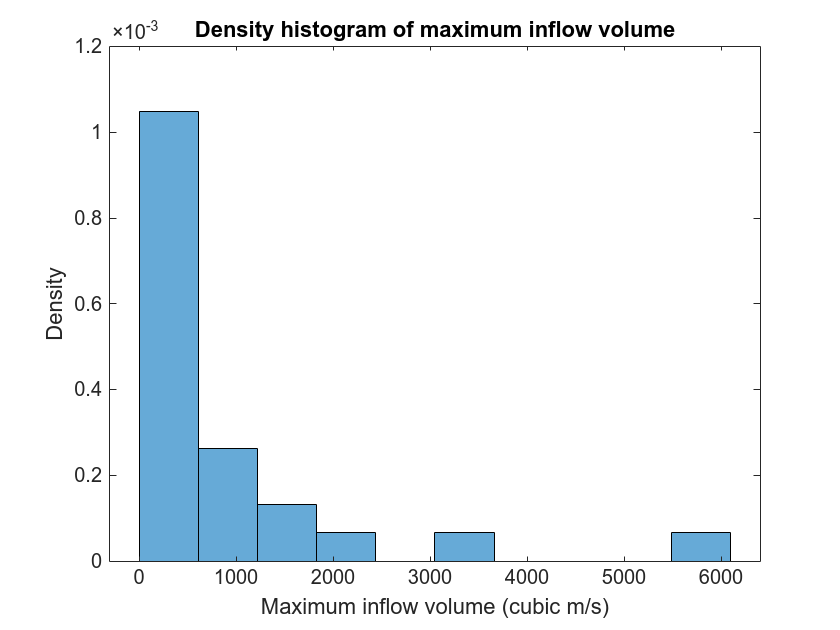

% Set how many bins we want MATLAB to use
% Change numBins to see how it affects the shape of the histogram
% Take note of how the vertical axis changes scale
numBins = 10; 

histogram(inflow, numBins, 'Normalization', 'pdf')
xlabel('Maximum inflow volume (cubic m/s)')
ylabel('Density')
title('Density histogram of maximum inflow volume')

Increasing the number of bins certainly improves the informativity of the histogram. When the bins are too wide (when `numBins` is small), we cannot assert local variability in the density. When the bins are too small (when `numBins` is large), we lose the global shape of the density. Hence, we see that there is a trade-off between shape and variability. We want to choose a selection of bins that maintains local variation and global shape. 

Let's reduce the bin-width where there are a lot of data—so that we increase local variation where it's important—and increase the bin-widths where there are few data. We can do this by manually selecting the edges of the bins. 

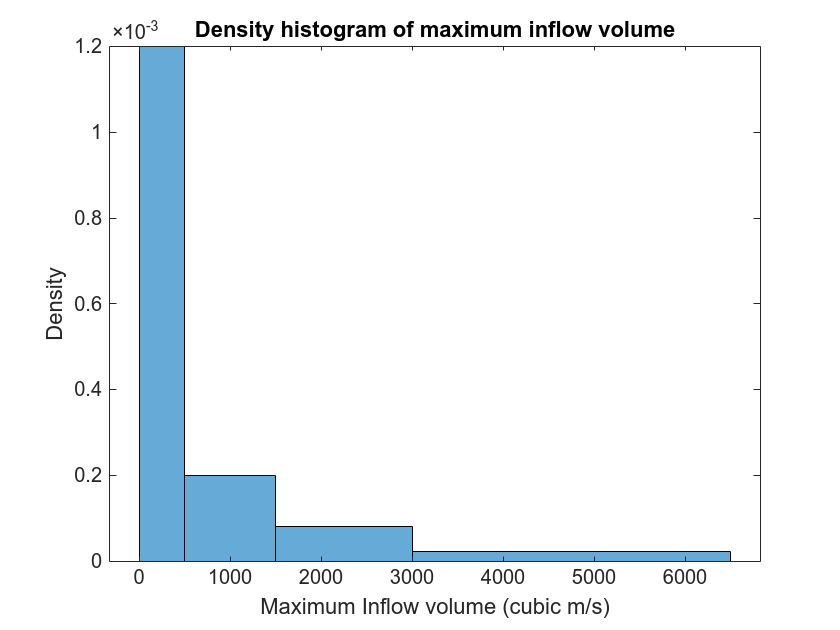

% Write the edges as a vector
edges = [0, 500, 1500, 3000, 6500];

% Use help histogram to see how applying a vector in the second argument
% changes the histogram
histogram(inflow, edges, 'Normalization', 'pdf')
xlabel('Maximum Inflow volume (cubic m/s)')
ylabel('Density')
title('Density histogram of maximum inflow volume')

The histogram looks a bit smoother now. We see that the vast majority of the data are located in the leftmost bin $[0, 500)$. The heights of the bin appear to decay exponentially. The histogram is *right-skewed*, since most of the data is concentrated on the left and there is a long tail that extends to the right. 

*Skewness is where the tail of the data are*. 

We hence expect the mean to be larger than the median. 

median(inflow)

ans = 412

mean(inflow)

ans = 862.8400

We use density histograms since they are theoretically consistent with probability density functions, and hence are reflective of the underlying nature of the data. The frequency histogram below implies that larger values, e.g., larger than 3 000, are more common than they actually are, as depicted in the previous density histogram. Hence, *we prefer to use density histograms*. 

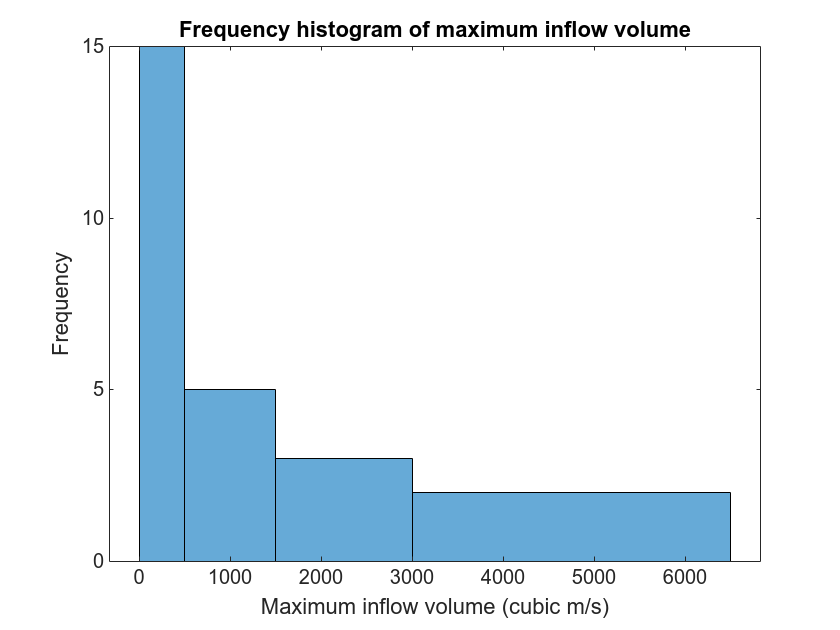

% Plot a frequency histogram using the same bin edges as before
histogram(inflow, edges)
xlabel('Maximum inflow volume (cubic m/s)')
ylabel('Frequency')
title('Frequency histogram of maximum inflow volume')

In general, we like working with symmetric data. Let's apply a log-transformation, since the data are right skewed. 

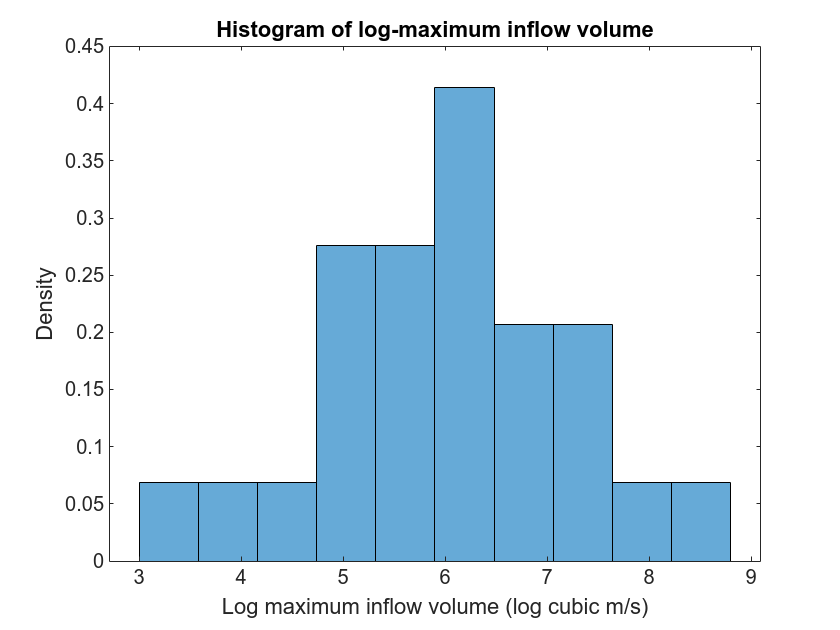

% Apply the log transformation
logInflow = log(inflow);

% Plot the log-inflows as a density histogram
histogram(logInflow, numBins, 'Normalization', 'pdf')
xlabel('Log maximum inflow volume (log cubic m/s)')
ylabel('Density')
title('Histogram of log-maximum inflow volume')

The `log()` function is the inverse of the `exp()` function. We apply the log-transformation to right-skewed since it doesn't change small values too much, but reduces the magnitude large values greatly. The resulting histogram of `log(Inflow)` is symmetric and follows the standard bell curve. We can quantify *skewness of the data through the quantity*

$g = \frac{1}{ns^{3}}\sum^{n}_{i = 1}\left(x_{i} - \overline{x}\right)^{3}$,

where $n$ is the sample size, $x_{1},\ldots,x_{n}$ are the sample observations, $\overline{x}$ is the sample mean, and $s$ is the sample standard deviation. The larger $g$ is, the more right-skewed the data. The smaller $g$ is—meaning *negative numbers with large magnitude*—the more left-skewed the data. If $g$ = 0, then the data are symmetric. 

skewness(inflow)

ans = 2.9253

skewness(logInflow)

ans = -0.0105

The raw sample has a skewness of $g_{\text{raw}}$ = 2.93, whilst the log-transformed data has a skewness of $g_{\text{log}}$ = -0.01. So our inspection of the symmetry of the histogram of the log-inflows is reinforced by the skewness quantity $g_{\text{log}}$.

## Question 3

In the previous question, the data were all numbers. However, the `presdat.txt` file contains names, which are processed as `strings` or `characters` in MATLAB. We can instead extract each column individually using `readvars()`, which can flexibly handle non-numeric data. MATLAB will store the character vectors `Name` and `Country` as `cell`-valued vectors. We need to coerce these `cell`-valued vectors to `string`-valued vectors. 

% Change the directory using cd to where the file location
cd /srv/hdrive/z3417078/teaching/MATH2089/data

% Store the individual columms using readvars()
% Writing a semi-colon ; at the end prevents printing to the console
[name, age, country] = readvars("presdat.txt");

% Set Name and Country to string vectors
name = string(name);
country = string(country);
ageAsString = string(age);

The data set contains Australian and American leaders. We only want data for the America leaders. We can subset out these elements by subsetting with respect to the logical vector `Country == 'US'`. This produces a sequences of `True` and `False` values, respectively encoded as 1 and 0.

% The logical vector returns 1 if the Country is 'US' for that index, and 0
% otherwise
country == 'US'

ans = 78×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


% Subsetting with respect to the logical vector Country == 'US' extracts
% only those elements for which the associated Country value is 'US'
nameUS = name(country == 'US');
ageUS = age(country == 'US');

Let's take a look at the ages of the American president against their presidential index. The `plot` function in MATLAB is the easiest way to do this. We see that the American presidential ages seemed to initially decrease up until the 26-th president (Theodore Roosevelt, 42, Inagurated: 1901), but have since increased. The most recent president (Biden, 78, Inagurated: 2021) is the oldest president. It also appears the variability in the presidential ages has increased. 

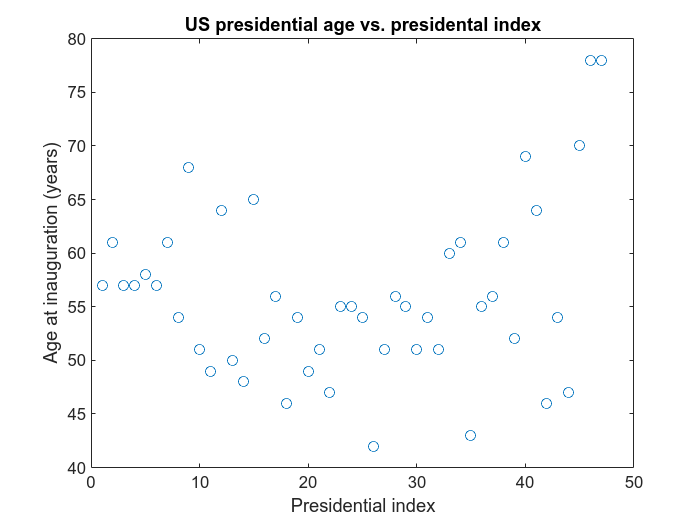

% See help plot for details
% Produce a point plot by specifying the mark 'o'
plot(ageUS, 'o')
xlabel("Presidential index")
ylabel("Age at inauguration (years)")
title("US presidential age vs. presidental index")

Let's take a look at a frequency histogram of the presidential ages.

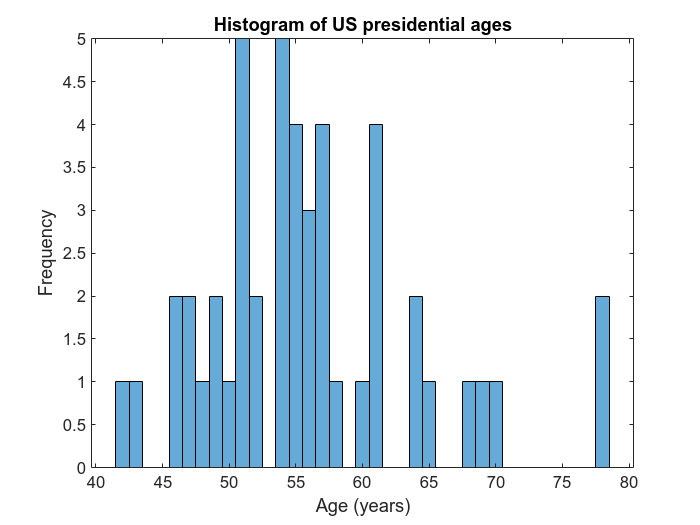

% Set the bins [42, 44), [45, 47), ..., [76, 78)
edges = 42:3:78;

% Let MATLAB produce the default histogram
histogram(ageUS)
xlabel("Age (years)")
ylabel("Frequency")
title("Histogram of US presidential ages")

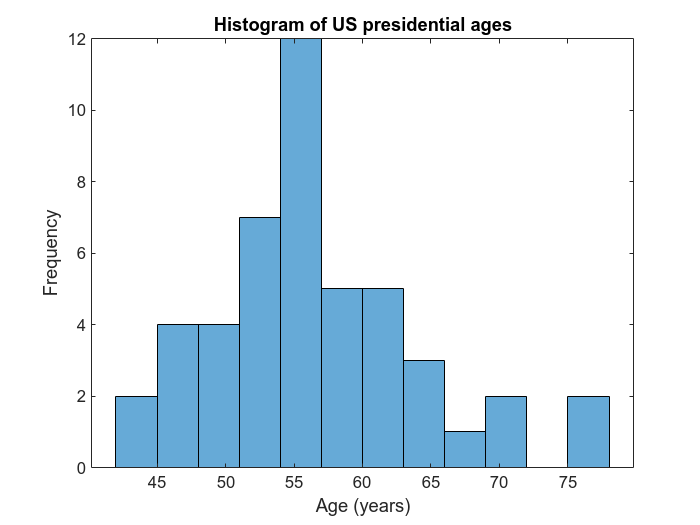

% Plot the histogram with customised edges
histogram(ageUS, edges)
xlabel("Age (years)")
ylabel("Frequency")
title("Histogram of US presidential ages")

The default MATLAB histogram uses bin-width 1. This introduces too much variability. The second histogram uses the bins $[42,44), [45, 47), \ldots [76, 78]$. The second histogram is more visually informative since we see that, historically, most American presidents were aged 50–60, with 55 being the centre of the roughly symmetric distribution. 

Let's compare the ages of the American presidents and Australian prime ministers.

% Subset the names and ages of only Australian prime ministers
nameAust = name(country == 'Aust');
ageAust = age(country == 'Aust');

% Produce a matrix of descriptive statistics
% Row 1: US
% Row 2: Aust
[mean(ageUS), var(ageUS), std(ageUS);
    mean(ageAust), var(ageAust), std(ageAust)]

ans =    55.9574   63.3895    7.9617
   52.5484   44.9892    6.7074


The average age of the US presidents and Australian prime ministers are respectively 55.48 years and 52.55 years. The standard deviation of presidential and prime ministerial ages are respectively 7.33 years and 6.71 years. Hence, Australian prime ministers are, on average, younger than the American presidents. It would be clearer to see this through comparative distributional diagrams.

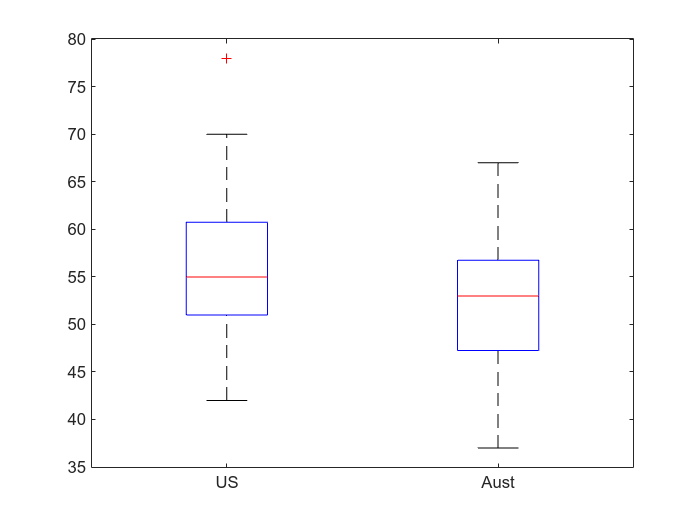

% Plot comparative boxplots with respect to the grouping defined by country
% See 'help boxplot' for details
boxplot(age, country)

Like histograms, comparative boxplots, are coarse representations of the density function. The bottom and topmost *whiskers* respectively identify the minimum and maximum of the data. The middle red line is the median, whilst the blue box identifies the interquartile range. The red '+' indicates outliers. The median age between American and Australian leads is similar. However, Australia has had younger leaders than America, and America has had older leaders in Australia.

Let's examine the five-number summaries for each of the data sets.

% Set the quantiles for the 5-number summary
quantiles = 0:0.25:1;

% Plot the comparative 5-number summary in a matrix
% Row 1: US
% Row 2: Australia
[quantile(ageUS, quantiles);
    quantile(ageAust, quantiles)]

ans =    42.0000   51.0000   55.0000   60.7500   78.0000
   37.0000   47.2500   53.0000   56.7500   67.0000


The 5-number summaries tell us that the youngest and oldest ages of the US presidents are 42 and 78. The m

## Question 4

Let's use `readvars()` again to import the `crash.txt` data set. As the data in `crash.txt` are all numeric, we could equivalently use `readmatrix()` and then assign the variables `head`, `chest`, `airbag`, ..., `weight` by subsetting out the matrix as we had done in Question 2. Directly assigning the variables in one line using `readvars()`  is a bit more elegant, since it saves space.

% Change the directory using cd to where the file location
cd H:\teaching\MATH2089\datasets

% Store the individual columms using readvars()
% Writing a semi-colon ; at the end prevents printing to the console
% Make sure that the variables are written in the correct order
[head, chest, airbag, doors, year, weight] = readvars("crash.txt");